clear ;
close all;

load ryan2_gen_data_new.mat

FNN 으로 테스트 - training set (test/validation 없이 )

feedforwardnet([50,10] => 2개충, 첫번째 50 뉴런, 두번째층 10 개 뉴런

=== 참조 ==

`hiddenSizes` **—** **Size of the hidden layers**

10 (default) | row vector

Size of the hidden layers in the network, specified as a row vector. The length of the vector determines the number of hidden layers in the network.

**Example:** For example, you can specify a network with 3 hidden layers, where the first hidden layer size is 10, the second is 8, and the third is 5 as follows: `[10,8,5]`

The input and output sizes are set to zero. The software adjusts the sizes of these during training according to the training data.

**Data Types:** `single` | `double`

[https://kr.mathworks.com/matlabcentral/answers/260613-validation-sets-vs-test-sets](https://kr.mathworks.com/matlabcentral/answers/260613-validation-sets-vs-test-sets)

`Total     = Design + Nondesign`

` Design    = Training + Validation`

` Nondesign = Testing`

` Total       = Training + Nontraining`

` Nontraining = Validation + Testing`

` Overfitting: Using more ``weights and biases than necessary`

` Overtraining: Improving the ``performance of the training data at the expense of deteriorating the performance`

` on ``nontraining data`

` Training ``data subset: Used to DIRECTLY estimate weights and biases. Performance estimates are BIASED.`

` Validation ``data subset: Used to `

` (1) determine ``when overtraining an overfit net begins to occur AND `

` (2) rank ``multiple designs. `

` Performance ``estimates are SIGNIFICANTLY LESS BIASED than training data estimates.`

` Test data subset: Used to obtain UNBIASED ESTIMATES of performance on nontraining (INCLUDING UNSEEN!) data`

[https://kr.mathworks.com/help/deeplearning/ref/dividerand.html](https://kr.mathworks.com/help/deeplearning/ref/dividerand.html)

`[`[`trainInd`](https://kr.mathworks.com/help/deeplearning/ref/dividerand.html#mw_1728d793-edc6-4595-8a0d-22992dffe813)`,`[`valInd`](https://kr.mathworks.com/help/deeplearning/ref/dividerand.html#mw_caf766f1-5912-45f0-919e-f903b9d313f4)`,`[`testInd`](https://kr.mathworks.com/help/deeplearning/ref/dividerand.html#mw_8e6cbc0b-a46a-4dbf-b95c-5eb6fcd46e9b)`] = dividerand(`[`Q`](https://kr.mathworks.com/help/deeplearning/ref/dividerand.html#mw_a6062bcf-a3b1-4224-9caa-fa872fae85d3)`,`[`trainRatio`](https://kr.mathworks.com/help/deeplearning/ref/dividerand.html#mw_72c9b34e-a329-46f2-a907-39b169c6e19a)`,`[`valRatio`](https://kr.mathworks.com/help/deeplearning/ref/dividerand.html#mw_2abef95f-2bd8-4aec-8a09-126cd5c93bcc)`,`[`testRatio`](https://kr.mathworks.com/help/deeplearning/ref/dividerand.html#mw_f4192d38-e08b-446c-af8a-ee0cc9472af8)`)`는 나눌 목표값의 개수, 훈련에 사용할 벡터의 비율, 검증에 사용할 벡터의 비율, 테스트에 사용할 벡터의 비율을 받고, 훈련 인덱스, 검증 인덱스, 테스트 인덱스를 반환합니다

[https://kr.mathworks.com/help/deeplearning/ug/divide-data-for-optimal-neural-network-training.html](https://kr.mathworks.com/help/deeplearning/ug/divide-data-for-optimal-neural-network-training.html)

훈련, 테스트 및 검증의 디폴트 비율은 각각 0.7, 0.15, 0.15입니다.

[https://kr.mathworks.com/help/deeplearning/ug/improve-neural-network-generalization-and-avoid-overfitting.html](https://kr.mathworks.com/help/deeplearning/ug/improve-neural-network-generalization-and-avoid-overfitting.html)

베이즈 정규화는 함수 [`trainbr`](https://kr.mathworks.com/help/deeplearning/ref/trainbr.html)에 구현되어 있습니다. 다음 코드는 이 함수를 사용하여 1-20-1 신경망이 [얕은 신경망 일반화를 개선하고 과적합 방지하기](https://kr.mathworks.com/help/deeplearning/ug/improve-neural-network-generalization-and-avoid-overfitting.html) 항목의 그림에 나와 있는 잡음이 있는 사인파를 근사하도록 훈련시키는 방법을 보여줍니다. ([`trainbr`](https://kr.mathworks.com/help/deeplearning/ref/trainbr.html)의 영향이 조기 중지로부터 격리되도록 `net.divideFcn`을 설정하여 데이터 분할이 취소되었습니다.)

`x = -1:0.05:1;`

`t = sin(2*pi*x) + 0.1*randn(size(x));`

`net = feedforwardnet(20,'trainbr');`

`net = train(net,x,t);`

xnorm = new_xnormall;
ynorm = new_ynormall;

- FNN1 - 1 layer


netFNN1_1 = feedforwardnet(10); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
netFNN1_1.divideFcn = 'divideind';
netFNN1_1.divideParam.trainInd = new_idxTrainRand;
netFNN1_1.divideParam.valInd = new_idxValidRand;
netFNN1_1.divideParam.testInd = new_idxTestRand; 
    
%netFNN1__1.divideParam
% https://kr.mathworks.com/matlabcentral/answers/314483-how-to-disable-popup-of-training-windows-for-neural-network-in-matlab
netFNN1_1.trainParam.showWindow = 0; 
netFNN1_1.trainParam.epochs = 300; % 전체 데이타를 300번 반복 이용해라
[netFNN1_1, tr] = train(netFNN1_1, xnorm', ynorm', 'useparallel',  'yes');

Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.


%tr

filterSize = 5;
numFilters = 32;
numFCN = 1;

- CNN1 : 2 Convolution Layer with filter size [1, 2] and number of filter 10, 5.

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:05 |         0.25 |         0.30 |       0.0319 |       0.0447 |          0.0010 |
|      50 |          50 |       00:00:09 |         0.12 |         0.21 |       0.0074 |       0.0227 |          0.0010 |
|     100 |         100 |       00:00:11 |         0.09 |         0.20 |       0.0044 |       0.0195 |          0.0010 |
|     150 |         150 |       00:00:14 |         0.08 |         0.20 |       0.0034 |   

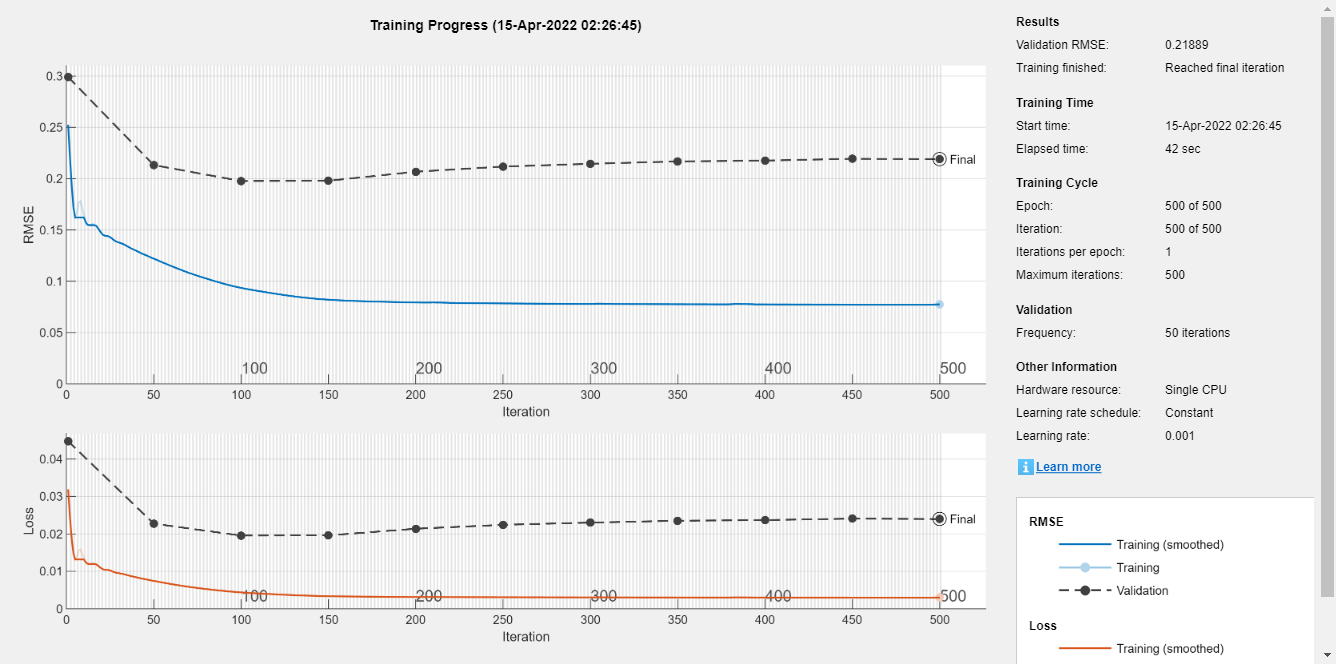

input_size = 100;
layerCNN2_1 = [
    imageInputLayer([1, input_size]);
    convolution2dLayer([1, filterSize], numFilters, 'Stride', 1);
    leakyReluLayer
    convolution2dLayer([1, filterSize], numFilters, 'Stride', 1);
    leakyReluLayer
    fullyConnectedLayer(numFCN)
    regressionLayer();
    ];
cellx = num2cell(xnorm', 1)';
cellx = cellfun(@transpose, cellx, 'UniformOutput', false);
cellyB = num2cell(ynorm);
tbl = table(cellx);
tbl.cellyB = cellyB;


Traintbl = tbl(tr.trainInd, :);
valtbl = tbl(tr.valInd, :);
testtbl = tbl(tr.testInd, :);

options = trainingOptions('adam', ...
 'InitialLearnRate', 0.001, ...
 'MaxEpochs',500, ...
 'MiniBatchSize',50, ...
 'Plots','training-progress', 'ValidationData', valtbl);

netCNN2_1 = trainNetwork(Traintbl, layerCNN2_1, options);



%

- CNN2 :2 Convolution Layer with filter size [1, 2] and number of filter 30, 15.

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:07 |         0.30 |         0.29 |       0.0447 |       0.0434 |          0.0010 |
|      50 |          50 |       00:00:12 |         0.14 |         0.20 |       0.0092 |       0.0206 |          0.0010 |
|     100 |         100 |       00:00:14 |         0.10 |         0.21 |       0.0054 |       0.0217 |          0.0010 |
|     150 |         150 |       00:00:15 |         0.08 |         0.27 |       0.0034 |   

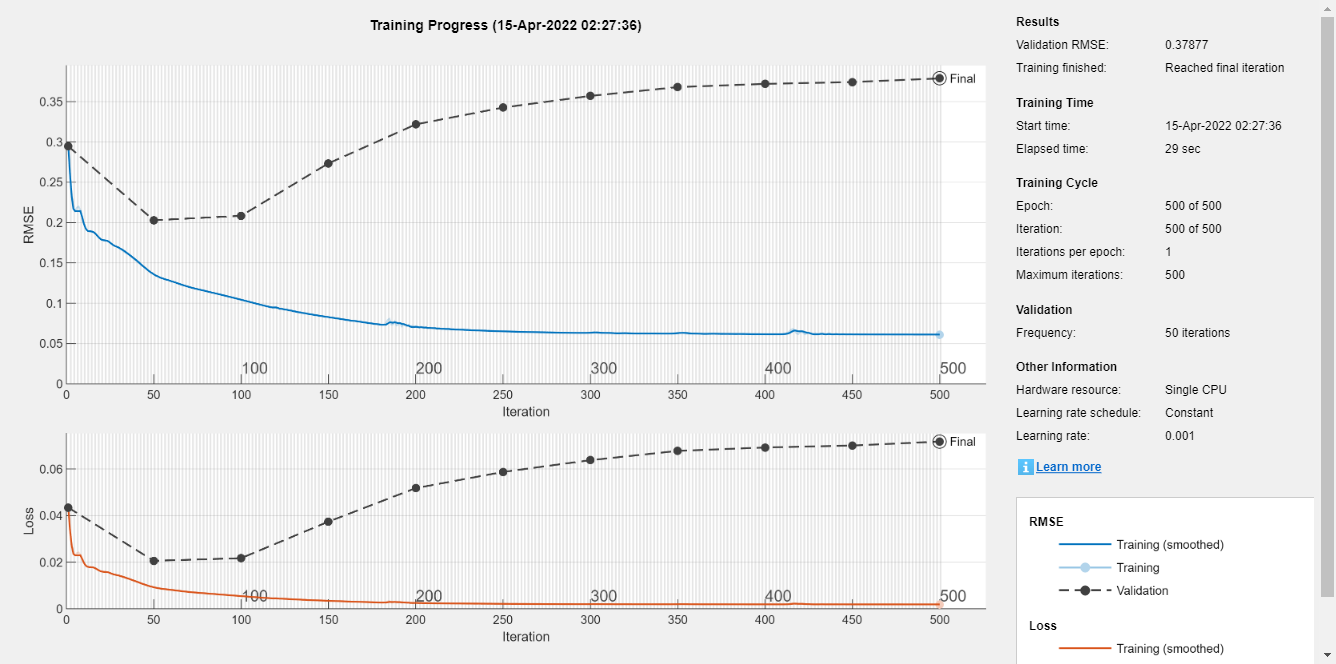

layerCNN2_2 = [
    imageInputLayer([1, input_size]);
    convolution2dLayer([1, 2*filterSize], 2*numFilters, 'Stride', 1);
    leakyReluLayer
    convolution2dLayer([1, 2*filterSize], 2*numFilters, 'Stride', 1);
    leakyReluLayer
    fullyConnectedLayer(numFCN)
    regressionLayer();
    ];

netCNN2_2 = trainNetwork(Traintbl, layerCNN2_1, options);

[https://kr.mathworks.com/help/deeplearning/ref/nnet.cnn.layer.convolution1dlayer.html](https://kr.mathworks.com/help/deeplearning/ref/nnet.cnn.layer.convolution1dlayer.html)

[https://kr.mathworks.com/help/deeplearning/ug/sequence-classification-using-1-d-convolutions.html](https://kr.mathworks.com/help/deeplearning/ug/sequence-classification-using-1-d-convolutions.html)

Create 1-D Convolutional Layer

Create a 1-D convolutional layer with numFilters filters of width of filterSize.

matlab 2021b 부터 지원

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:20 |         0.40 |         0.35 |       0.0814 |       0.0624 |          0.0010 |
|      50 |          50 |       00:00:31 |         0.19 |         0.23 |       0.0186 |       0.0253 |          0.0010 |
|     100 |         100 |       00:00:37 |         0.16 |         0.22 |       0.0129 |       0.0246 |          0.0010 |
|     150 |         150 |       00:00:42 |         0.14 |         0.22 |       0.0101 |   

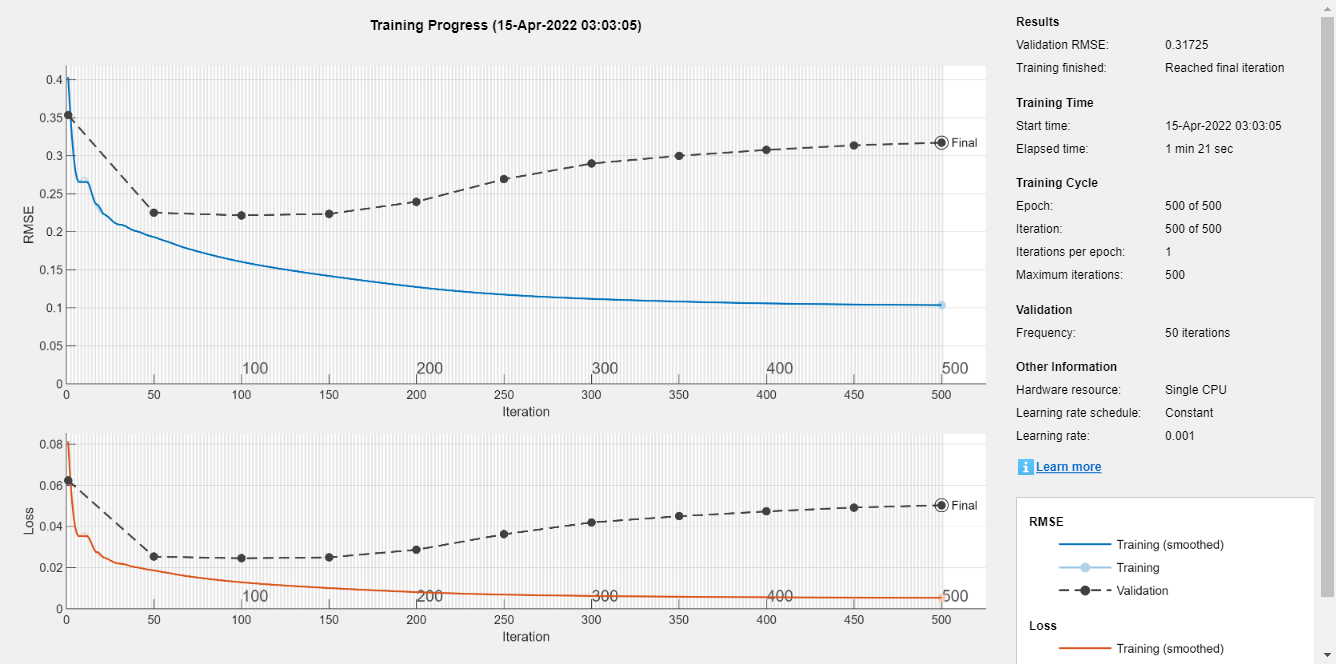



layerCNN1_1 = [
    imageInputLayer([1, input_size]);
    convolution2dLayer([1, filterSize], numFilters, 'Stride', 1);
    leakyReluLayer
    fullyConnectedLayer(numFCN)
    regressionLayer();
    ];
%     sequenceInputLayer(input_size)
%     convolution1dLayer(filterSize,numFilters)
%     reluLayer
%     globalMaxPooling1dLayer
%     fullyConnectedLayer(numFCN)
%     %softmaxLayer
%     regressionLayer();]
netCNN1_1 = trainNetwork(Traintbl, layerCNN1_1, options);

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:20 |         0.92 |         0.42 |       0.4193 |       0.0880 |          0.0010 |
|      50 |          50 |       00:00:27 |         0.17 |         0.24 |       0.0151 |       0.0280 |          0.0010 |
|     100 |         100 |       00:00:36 |         0.16 |         0.23 |       0.0136 |       0.0264 |          0.0010 |
|     150 |         150 |       00:00:48 |         0.16 |         0.23 |       0.0129 |   

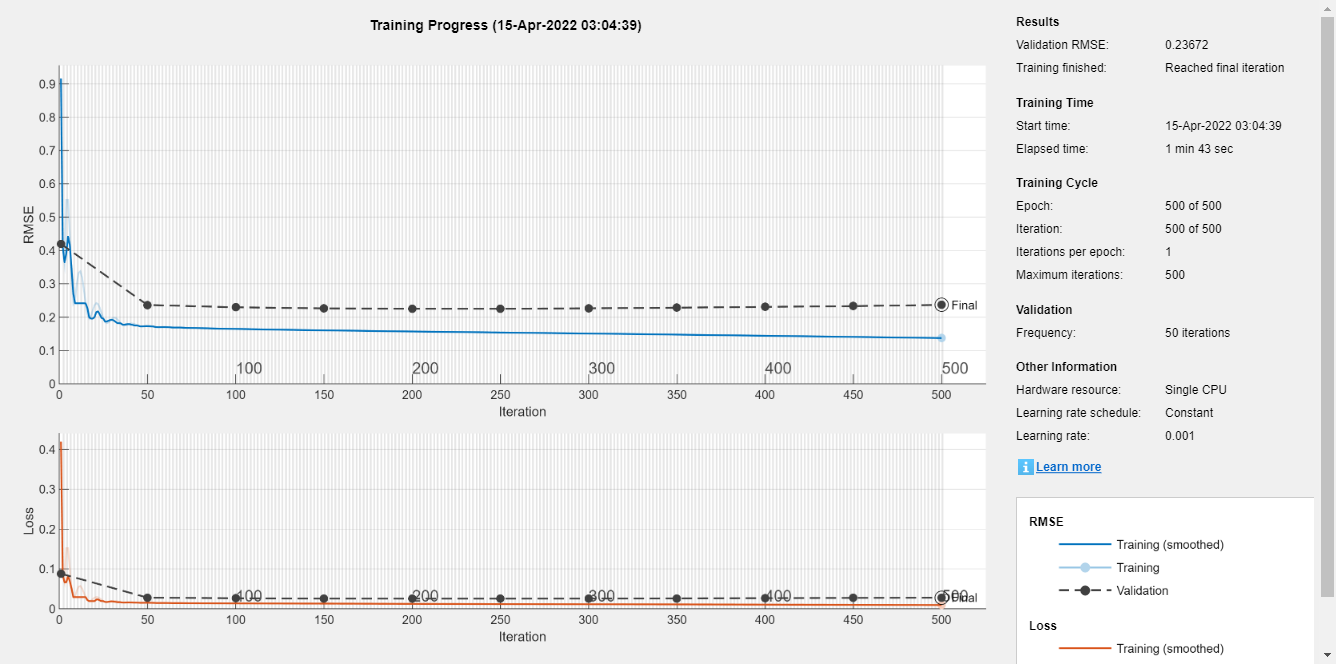



layerCNN2_3 = [ ...
    imageInputLayer([1, input_size]);
    convolution2dLayer([1, filterSize], numFilters, 'Stride', 1);
    reluLayer
    layerNormalizationLayer
    convolution2dLayer([1, filterSize], numFilters, 'Stride', 1);
    reluLayer
    layerNormalizationLayer
    globalAveragePooling2dLayer
    fullyConnectedLayer(numFCN)
    %softmaxLayer
    regressionLayer();];
netCNN2_3 = trainNetwork(Traintbl, layerCNN2_3, options);

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:18 |         0.87 |         1.70 |       0.3786 |       1.4489 |          0.0010 |
|      50 |          50 |       00:00:39 |         0.18 |         0.23 |       0.0171 |       0.0265 |          0.0010 |
|     100 |         100 |       00:00:52 |         0.17 |         0.23 |       0.0147 |       0.0264 |          0.0010 |
|     150 |         150 |       00:01:13 |         0.16 |         0.23 |       0.0135 |   

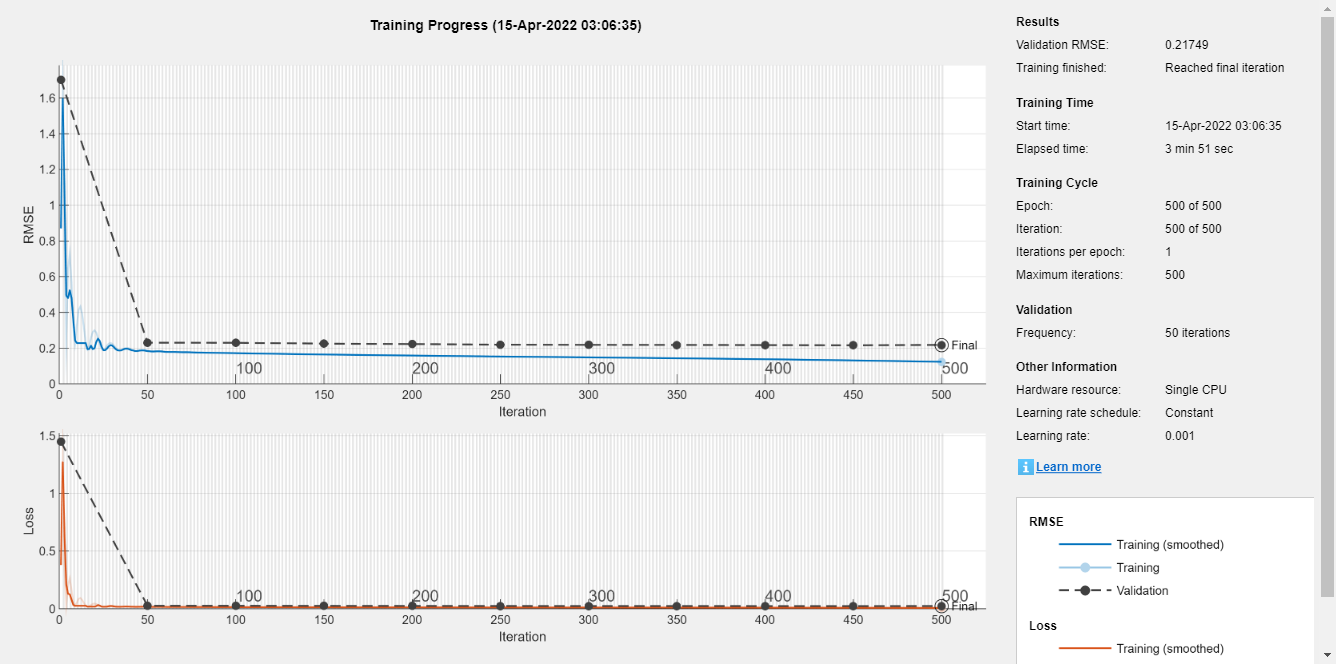


layerCNN2_4 = [ ...
    imageInputLayer([1, input_size]);
    convolution2dLayer([1, 2*filterSize], 2*numFilters, 'Stride', 1);
     reluLayer
    layerNormalizationLayer
    convolution2dLayer([1, 2*filterSize], 2*numFilters, 'Stride', 1);
    reluLayer
    layerNormalizationLayer
    globalAveragePooling2dLayer
    fullyConnectedLayer(numFCN)
    %softmaxLayer
    regressionLayer();];
netCNN2_4 = trainNetwork(Traintbl, layerCNN2_4, options);

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:53 |         0.59 |         3.41 |       0.1760 |       5.8050 |          0.0010 |
|      50 |          50 |       00:02:54 |         0.16 |         0.23 |       0.0121 |       0.0255 |          0.0010 |
|     100 |         100 |       00:05:28 |         0.15 |         0.22 |       0.0111 |       0.0246 |          0.0010 |
|     150 |         150 |       00:06:46 |         0.14 |         0.22 |       0.0105 |   

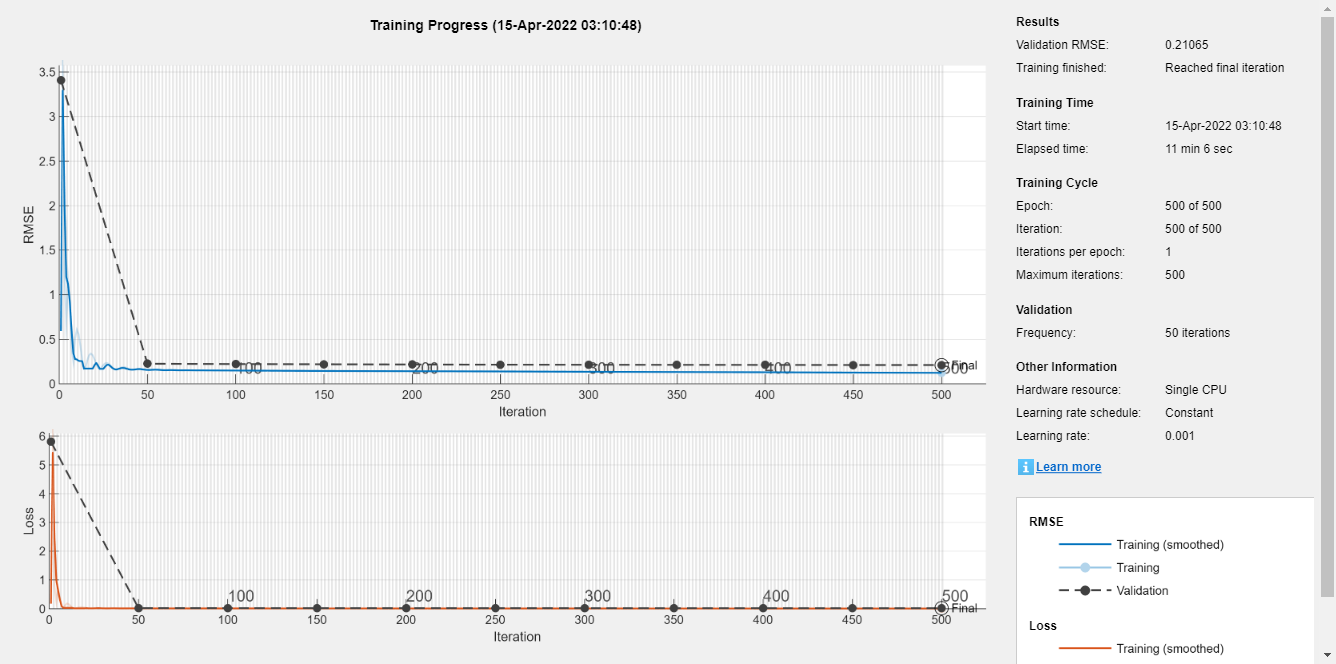


layerCNN3_1 = [ ...
    imageInputLayer([1, input_size]);
    convolution2dLayer([1, 2*filterSize], 2*numFilters, 'Stride', 1);
    reluLayer
    layerNormalizationLayer
    convolution2dLayer([1, 2*filterSize], 2*numFilters, 'Stride', 1);
    reluLayer
    layerNormalizationLayer
    convolution2dLayer([1, 2*filterSize], 2*numFilters, 'Stride', 1);
    reluLayer
    layerNormalizationLayer    
    globalAveragePooling2dLayer
    fullyConnectedLayer(numFCN)
    %softmaxLayer
    regressionLayer();];
netCNN3_1 = trainNetwork(Traintbl, layerCNN3_1, options);

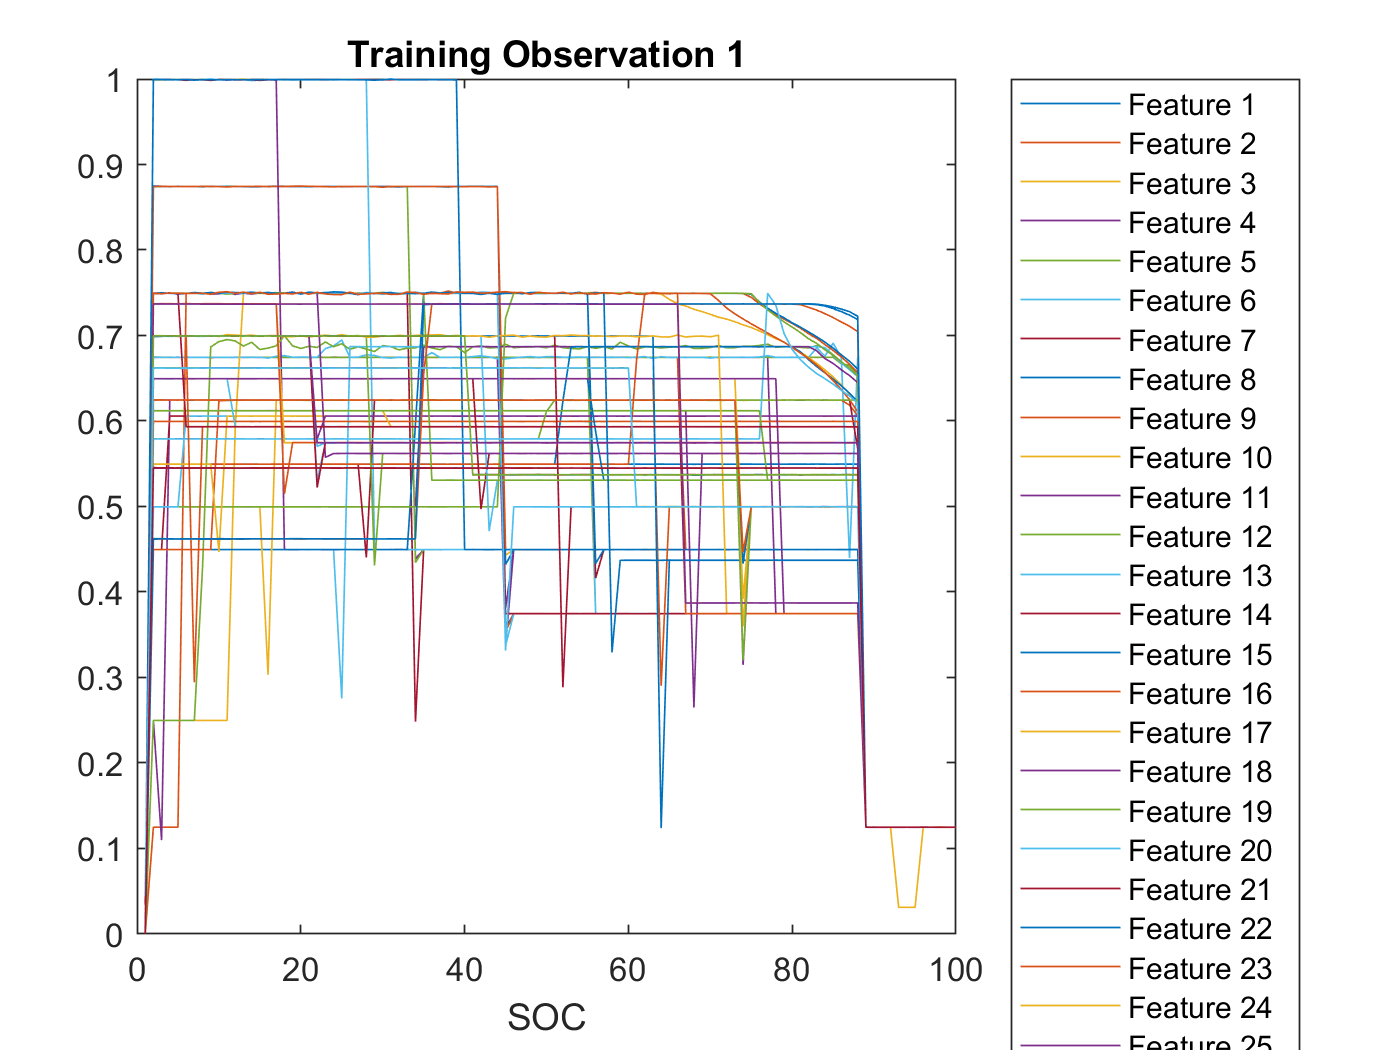

figure
plot(xnorm')
xlabel("SOC")
title("Training Observation 1")
numFeatures = size(xnorm,1);
legend("Feature " + string(1:numFeatures),Location="northeastoutside")

cellx = num2cell(xnorm(tr.testInd, :)', 1)';
cellx = cellfun(@transpose, cellx, 'UniformOutput', false);
tbl = table(cellx);

x_4d = zeros(1, input_size, 1, height(tbl));
for i = 1:height(tbl)
    x_4d(:,:,:,i) = tbl.cellx{i};
end


pCNN2_1 = predict(netCNN2_1, x_4d);
pCNN2_2 = predict(netCNN2_2, x_4d);
pCNN2_3 = predict(netCNN2_3, x_4d);
pCNN2_4 = predict(netCNN2_4, x_4d);
pCNN1_1 = predict(netCNN1_1, x_4d);
pCNN3_1 = predict(netCNN3_1, x_4d);


ytest = ynorm(tr.testInd, :)*yrate + ymin;
pCNN2_1_hat = pCNN2_1 * yrate + ymin;
pCNN2_2_hat = pCNN2_2 * yrate + ymin;
pCNN2_3_hat = pCNN2_3 * yrate + ymin;
pCNN2_4_hat = pCNN2_4 * yrate + ymin;
pCNN1_1_hat = pCNN1_1 * yrate + ymin;
pCNN3_1_hat = pCNN3_1 * yrate + ymin;

rmse_pCNN2_1_hat = sqrt(mean(( ytest' - pCNN2_1_hat' ).^2))

rmse_pCNN2_1_hat = single
148.7402

rmse_pCNN2_2_hat = sqrt(mean(( ytest' - pCNN2_2_hat' ).^2))

rmse_pCNN2_2_hat = single
103.5702

rmse_pCNN2_3_hat = sqrt(mean(( ytest' - pCNN2_3_hat' ).^2))

rmse_pCNN2_3_hat = single
111.6466

rmse_pCNN2_4_hat = sqrt(mean(( ytest' - pCNN2_4_hat' ).^2))

rmse_pCNN2_4_hat = single
58.5619

rmse_pCNN1_1_hat = sqrt(mean(( ytest' - pCNN1_1_hat' ).^2))

rmse_pCNN1_1_hat = single
159.1053

rmse_pCNN3_1_hat = sqrt(mean(( ytest' - pCNN3_1_hat' ).^2))

rmse_pCNN3_1_hat = single
110.7996

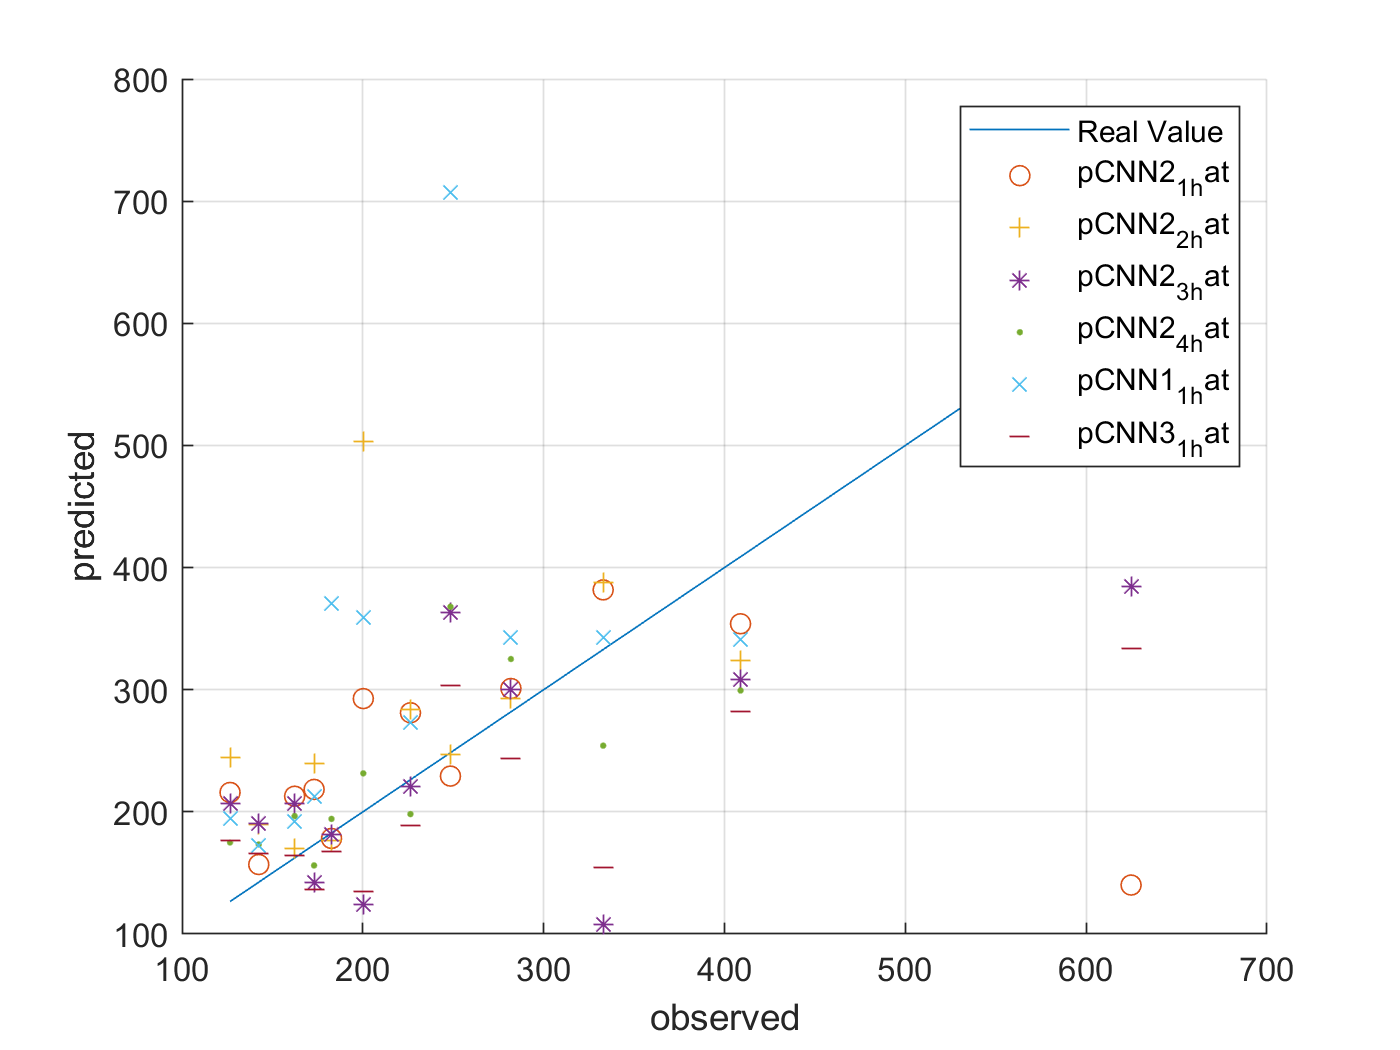




figure, hold on, grid on,
plot(ytest,ytest)
plot(ytest,pCNN2_1_hat,'o')
plot(ytest,pCNN2_2_hat,'+')
plot(ytest,pCNN2_3_hat,'*')
plot(ytest,pCNN2_4_hat,'.')
plot(ytest,pCNN1_1_hat,'x')
plot(ytest,pCNN3_1_hat,'_')

hold off

xlabel 'observed'
ylabel 'predicted'
legend(	'Real Value', ... 
		'pCNN2_1_hat', ... 
		'pCNN2_2_hat', ...
		'pCNN2_3_hat', ... 	
		'pCNN2_4_hat', ... 
        'pCNN1_1_hat', ... 
		'pCNN3_1_hat')



save('ryan2_gen_data_model_new.mat','netCNN2_1' ,'-append')
save('ryan2_gen_data_model_new.mat','netCNN2_2' ,'-append')
save('ryan2_gen_data_model_new.mat','netCNN2_3' ,'-append')
save('ryan2_gen_data_model_new.mat','netCNN2_4' ,'-append')
save('ryan2_gen_data_model_new.mat','netCNN1_1' ,'-append')
save('ryan2_gen_data_model_new.mat','netCNN3_1' ,'-append')

cellx_self = num2cell(xnorm([tr.trainInd tr.valInd], :)', 1)';
cellx_self = cellfun(@transpose, cellx_self, 'UniformOutput', false);
tbl_self = table(cellx_self);

x_4d_self = zeros(1, input_size, 1, height(tbl_self));
for i = 1:height(tbl_self)
    x_4d_self(:,:,:,i) = tbl_self.cellx_self{i};
end

pCNN2_1_self = predict(netCNN2_1, x_4d_self);
pCNN2_2_self = predict(netCNN2_2, x_4d_self);
pCNN2_3_self = predict(netCNN2_3, x_4d_self);
pCNN2_4_self = predict(netCNN2_4, x_4d_self);
pCNN1_1_self = predict(netCNN1_1, x_4d_self);
pCNN3_1_self = predict(netCNN3_1, x_4d_self);

ytrain_self = ynorm([tr.trainInd tr.valInd], :)*yrate + ymin;
pCNN2_1_self_hat = pCNN2_1_self * yrate + ymin;
pCNN2_2_self_hat = pCNN2_2_self * yrate + ymin;
pCNN2_3_self_hat = pCNN2_3_self * yrate + ymin;
pCNN2_4_self_hat = pCNN2_4_self * yrate + ymin;
pCNN1_1_self_hat = pCNN1_1_self * yrate + ymin;
pCNN3_1_self_hat = pCNN3_1_self * yrate + ymin;


rmse_pCNN2_1_self_hat = sqrt(mean(( ytrain_self' - pCNN2_1_self_hat' ).^2))

rmse_pCNN2_1_self_hat = single
124.0602

rmse_pCNN2_2_self_hat = sqrt(mean(( ytrain_self' - pCNN2_2_self_hat' ).^2))

rmse_pCNN2_2_self_hat = single
142.5306

rmse_pCNN2_3_self_hat = sqrt(mean(( ytrain_self' - pCNN2_3_self_hat' ).^2))

rmse_pCNN2_3_self_hat = single
108.7904

rmse_pCNN2_4_self_hat = sqrt(mean(( ytrain_self' - pCNN2_4_self_hat' ).^2))

rmse_pCNN2_4_self_hat = single
99.4084

rmse_pCNN1_1_self_hat = sqrt(mean(( ytrain_self' - pCNN1_1_self_hat' ).^2))

rmse_pCNN1_1_self_hat = single
164.4373

rmse_pCNN3_1_self_hat = sqrt(mean(( ytrain_self' - pCNN3_1_self_hat' ).^2))

rmse_pCNN3_1_self_hat = single
105.9805

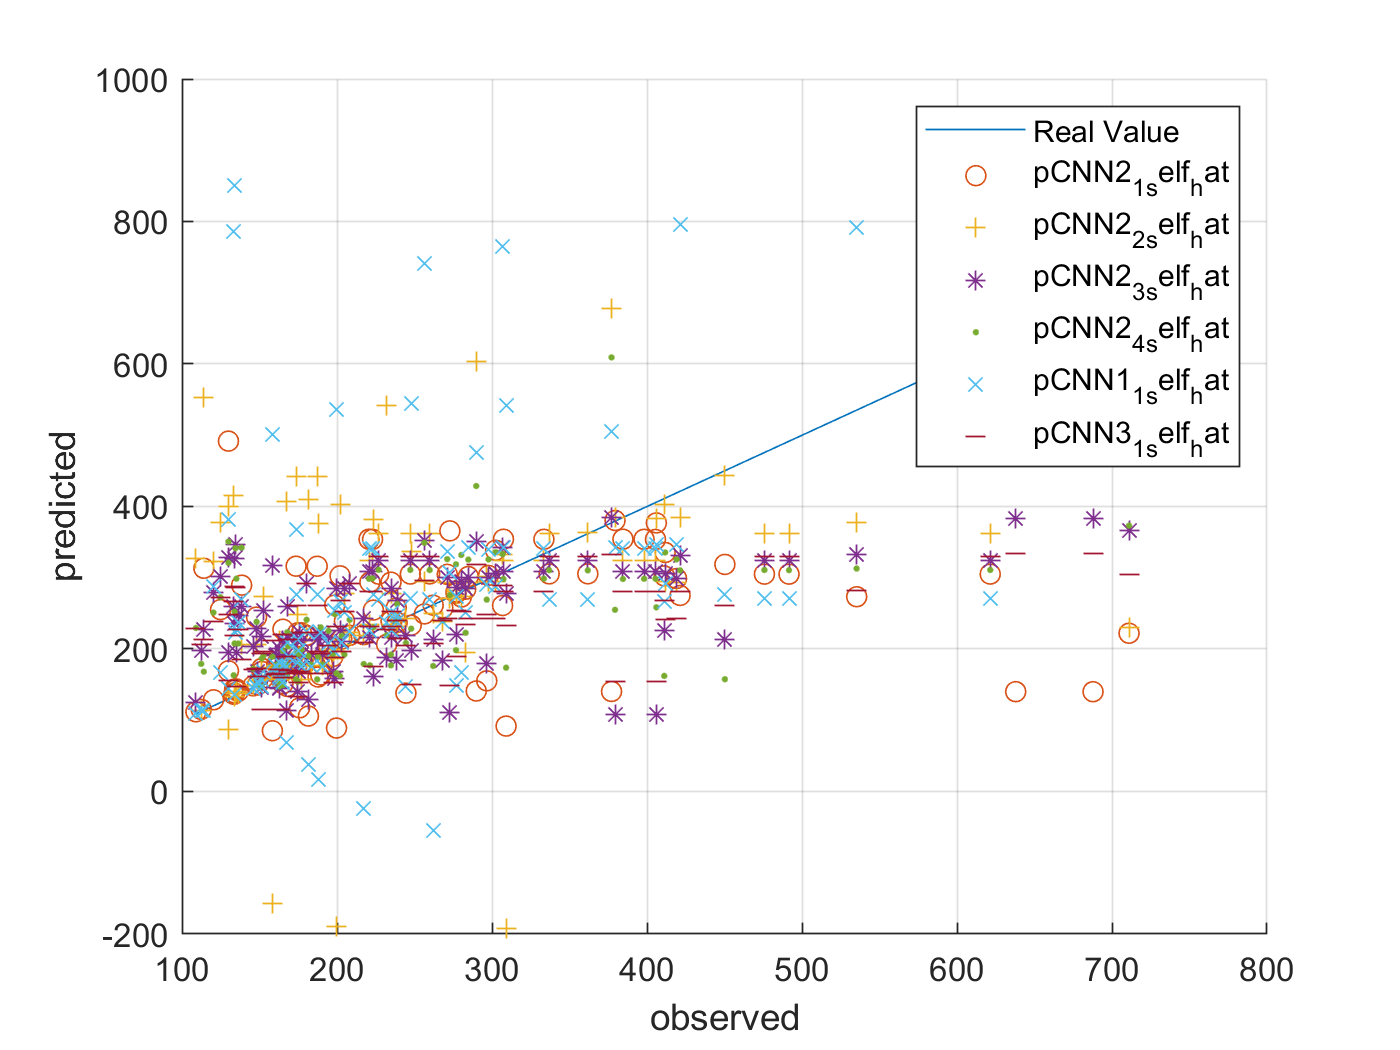




figure, hold on, grid on,
plot(ytrain_self,ytrain_self)
plot(ytrain_self,pCNN2_1_self_hat,'o')
plot(ytrain_self,pCNN2_2_self_hat,'+')
plot(ytrain_self,pCNN2_3_self_hat,'*')
plot(ytrain_self,pCNN2_4_self_hat,'.')
plot(ytrain_self,pCNN1_1_self_hat,'x')
plot(ytrain_self,pCNN3_1_self_hat,'_')

hold off

xlabel 'observed'
ylabel 'predicted'
legend(	'Real Value', ... 
		'pCNN2_1_self_hat', ... 
		'pCNN2_2_self_hat', ...
		'pCNN2_3_self_hat', ... 	
		'pCNN2_4_self_hat', ... 
        'pCNN1_1_self_hat', ...
		'pCNN3_1_self_hat')